v = [1/5; 1/5; 1/5; 1/5; 1/5];
A = [0 1/2 1/2 1/3 1/2; 0 0 1/2 0 0; 1 1/2 0 1/3 0; 0 0 0 0 1/2; 0 0 0 1/3 0];
for i = 2:20
    v(:,i) = A*v(:,i-1);
    v(:,i);
end
v(:,20)

ans =     0.3333
    0.2222
    0.4444
    0.0000
    0.0000


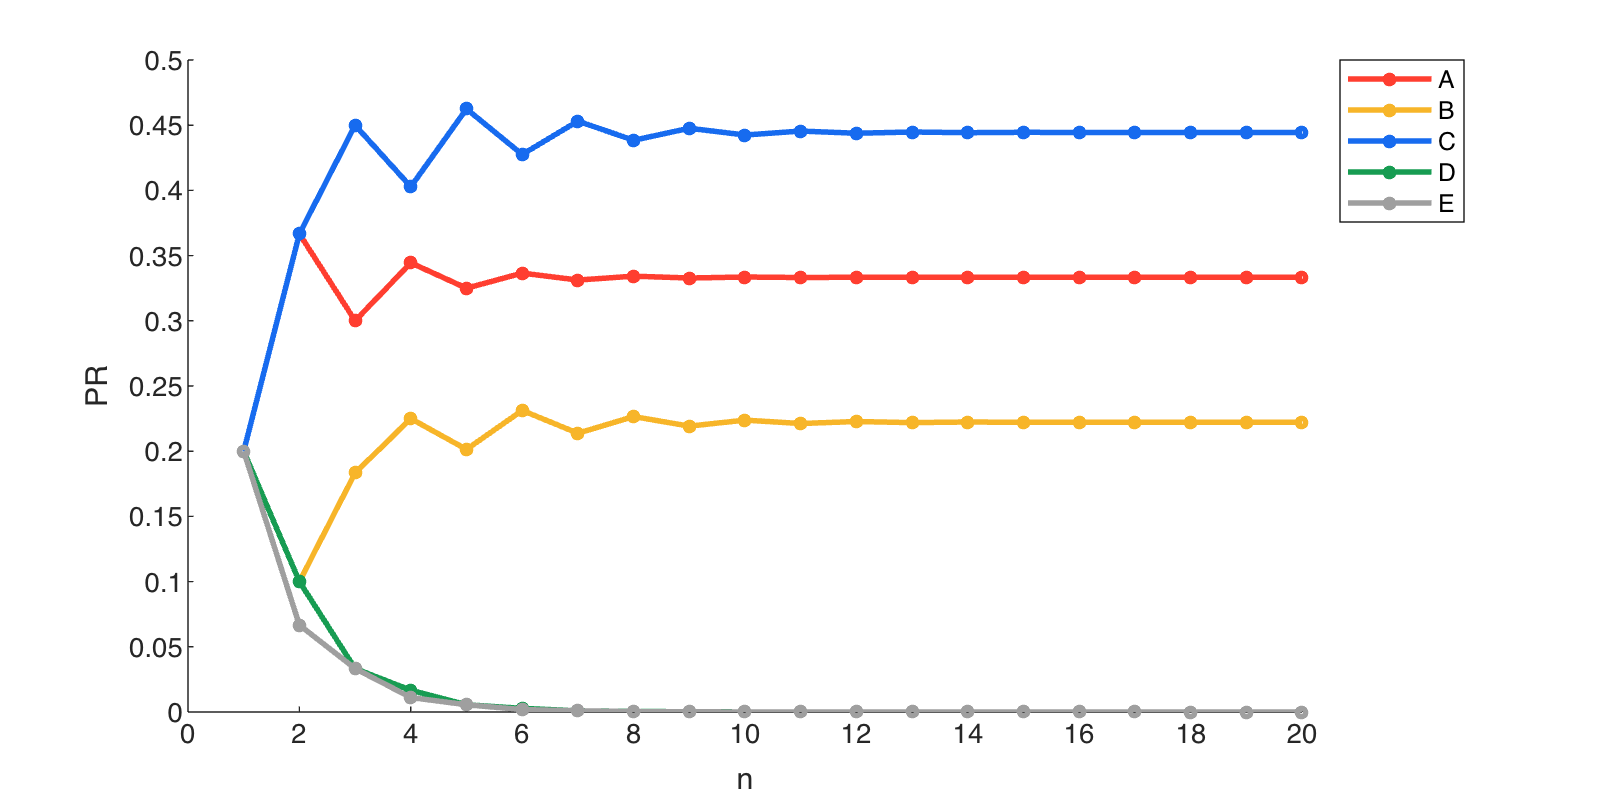

n = [1:20];
clf
hold on
plot(n,v(1,:), '-o', 'Color', [1 62/255 48/255], 'LineWidth', 2, 'MarkerSize', 3)
plot(n,v(2,:), '-o', 'Color', [247/255 181/255 41/255], 'LineWidth', 2, 'MarkerSize', 3)
plot(n,v(3,:), '-o', 'Color', [23/255, 107/255 239/255], 'LineWidth', 2, 'MarkerSize', 3)
plot(n,v(4,:), '-o', 'Color', [23/255 156/255 82/255], 'LineWidth', 2, 'MarkerSize', 3)
plot(n,v(5,:), '-o', 'Color', [159/255 159/255 159/255], 'LineWidth', 2, 'MarkerSize', 3)
legend(['A';'B';'C';'D';'E'], 'location','northeastoutside')
xlabel('n')
ylabel('PR')
set(gcf, 'position', [10 10 800 400])